syms x
f=@(n) (1/(2^n*factorial(n)))*diff((x^2-1)^n,n)

f = function_handle with value:
    @(n)(1/(2^n*factorial(n)))*diff((x^2-1)^n,n)


f(5)

$$ans = \frac{15\,x\,{\left(x^{2}-1\right)}^{2}}{8}+5\,x^{3}\,\left(x^{2}-1\right)+x^{5}$$

simplify(ans)

$$ans = \frac{x\,\left(63\,x^{4}-70\,x^{2}+15\right)}{8}$$

clear;clc;close;

f = function_handle with value:
    @(n)(1/(2^n*factorial(n)))*diff((x^2-1)^n,n)


x=linspace(-1,1,100);
P0=1;
P1=x;
P2=(1/2)*(3*x.^2-1);
P3=(1/2)*(5*x.^3-3*x);
P4=(1/8)*(35*x.^4-30*x.^2+3);
P5=(1/8)*(63*x.^5-70*x.^3+15*x);
plot([-1 1],[1 1],'lineWidth',2);
hold on
plot(x,P1,x,P2,x,P3,x,P4,x,P5);
legend('P0','P1','P2','P3','P4','P5','Location','best');

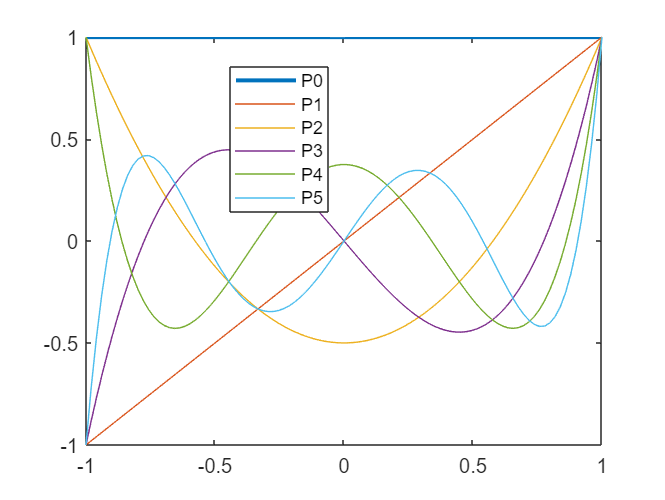

clear;clc;close;
syms x

f=@(n) (1/(2^n*factorial(n)))*diff((x^2-1)^n,n)
x=linspace(-1,1,100);
for i=1:5
    G=simplify(f(i));

f = function_handle with value:
    @(n)(1/(2^n*factorial(n)))*diff((x^2-1)^n,n)


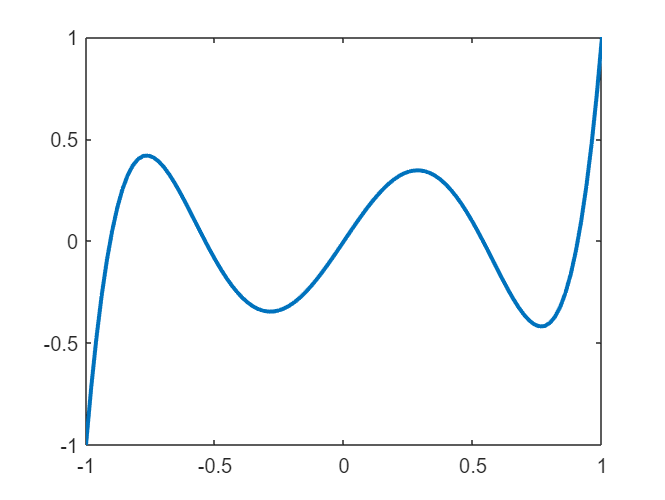

    H=matlabFunction(G);
    plot(x,H(x),'LineWidth',2);
end